# Estimation, Filtering and Detection

## Homework 3B: Current Sensor Fault

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

% Design healthy (m=1) state-space model
% Design faulty  (m=2) state-space model
% Find controller gain K_p to keep current limited to 200 A and no
% overshoot
% Analyze observability of m1
% Analyze observability of m2

% Motor parameters
R = 0.1;                % Ohms
L = 0.5;                % Henrys
Km = 0.5;               % motor constant
J = 10;                 % kg.m^2/s^2
Kp = 3;
% Healthy system m=1

A = [0 Km/J; -Kp/L -(R+Km)/L];
B = [0 1/J; Kp/L 0];
C = [1 0;0 1];
D = 0;
sys_healthy = ss(A,B,C,D);

% Faulty system m=2

A_f = A;
B_f = B;
C_f = [1 0;0 0];
D_f = 0;
sys_faulty = ss(A_f,B_f,C_f,D_f);

% Observability
disp("Observability of healthy system")

Observability of healthy system


Ob_healthy = obsv(A,C);
unobsv = length(A) - rank(Ob_healthy)

unobsv = 0

disp("Observability of faulty system")

Observability of faulty system


Ob_faulty = obsv(A_f,C_f);
unobsv = length(A_f) - rank(Ob_faulty)

unobsv = 0

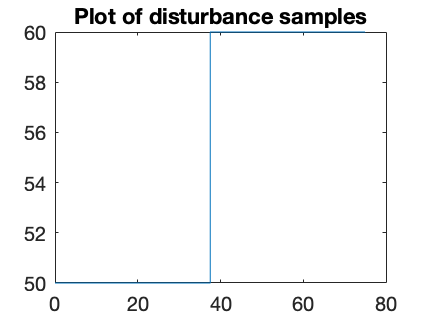




% disturbance
Ts = 0.05;
N = 1500;
T = Ts*N;
t = 0:Ts:T;
load = 50;        % Nm
deviation = 10;
Td = load*ones(1,N); % load disturbance
for i=1:N
      if i>N/2 && i<=N
         Td(i) = Td(i) + deviation;
      end
end
Td = [load Td];
figure;
plot(t,Td);
title("Plot of disturbance samples");

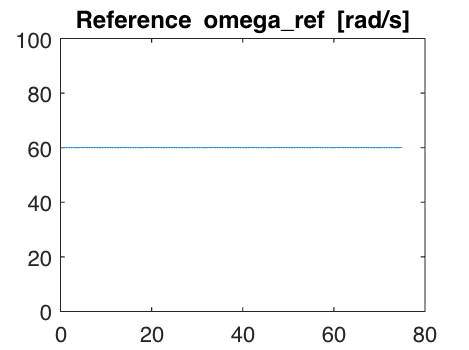


% refference signal
w_ref = 60*ones(size(t));
figure();
plot(t,w_ref);
ylim([0 100]);
title("Reference omega\_ref [rad/s]");

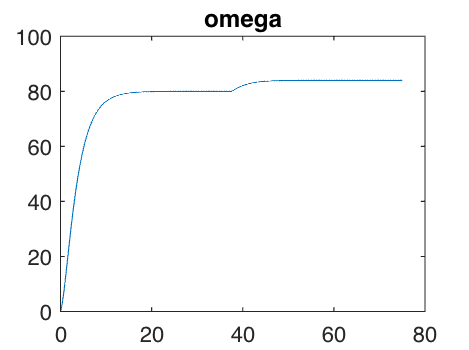


u = [w_ref;Td];
response = lsim(sys_healthy,u,t);
figure;
plot(t,response(:,1));
title("omega");

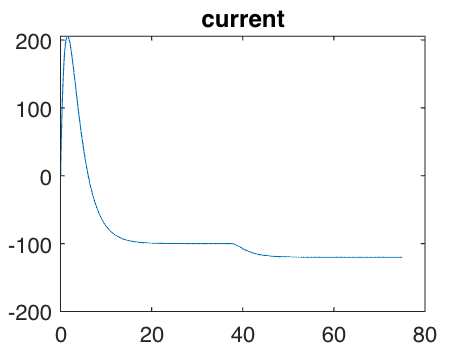

figure;
plot(t,response(:,2));
title("current");

## Problem 2:

% Select and justify process noise properties
% Find input-output data with multiple sensor faults

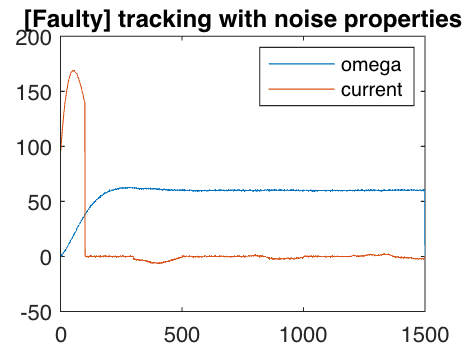

% noise properties
Qc = 0.01; % selected as 10 times lower than measurement noise
Rc = 0.1;
etta = 1; % selected as 1 (Tc=0) for synchronous sampling purposes

% healthy
Ah = expm(A*Ts);
Bh = inv(A)*(expm(A*Ts)-expm(A*0))*B;
Ch = C*expm(A*etta*Ts);
Dh = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;

Qh = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
Sh = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
Rh = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';

% faulty
Af = expm(A_f*Ts);
Bf = inv(A_f)*(expm(A_f*Ts)-expm(A_f*0))*B_f;
Cf = C_f*expm(A_f*etta*Ts);
Df = C_f*inv(A_f)*(expm(A_f*etta*Ts)-expm(A_f*0))*B_f;

Qf = Qc*inv(A_f+A_f')*(expm((A_f+A_f')*Ts) -expm((A_f+A_f')*0));
Sf = Qc*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';
Rf = Rc + C_f*Qc*inv(A_f+A_f')*(expm((A_f+A_f')*etta*Ts) -expm((A_f+A_f')*0))*C_f';

Kp = 0.5;
Ki = 0.25;
Kd = 0.25;
x = zeros(2,N);
y = zeros(2,N);
integral = 0;
last_error = 0;

for i=1:(N-1)
    error = (w_ref(i) - x(1,i));
    integral = integral + error*Ts; 
    u(:,i) = [Kp*error+Ki*integral + Kd*(error - last_error)/Ts;0];
    if ((i>100) && (i<300))||((i>500) && (i<700))||((i>1000) && (i<1200))
        % faulty
        x(:,i+1) = Af*x(:,i) + Bf*u(:,i) + sqrtm(Qh)*randn(2, 1);
        y(:,i)   = Cf*x(:,i) + Df*u(:,i) + sqrtm(Rh)*randn(2, 1);
    else
        % normal
        x(:,i+1) = Ah*x(:,i) + Bh*u(:,i) + sqrtm(Qf)*randn(2, 1);
        y(:,i)   = Ch*x(:,i) + Dh*u(:,i) + sqrtm(Rf)*randn(2, 1);
    end
    last_error = error;
end
figure();
plot(y(1,:));
hold on
plot(y(2,:));
legend("omega","current")
title("[Faulty] tracking with noise properties")
hold off

## Problem 3:

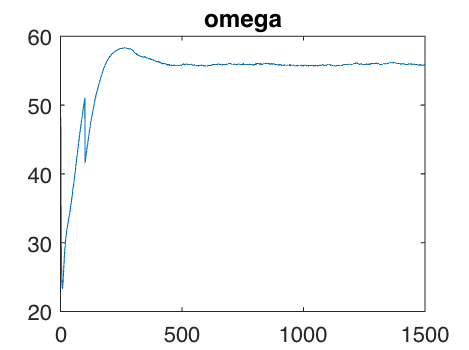

% Design IMM algorithm
% Evaluate unmeasurable load
% Detect faults of current sensor
% p12 = 0.001 transition to fault
% p21 = 0.005 recovery
pCorr = eye(2);
transProb = [0.001,0.005];
xCorrStored = zeros(2,length(y(1,:)));
estimatedLoad = zeros(1,length(y(1,:)));
for i = 1:length(y(1,:))
    detection_h = objectDetection(i,y(2,i));
    detection_f = objectDetection(i,0);
    filter = {initcvkf(detection_h),initcvkf(detection_f)};
    imm = trackingIMM('State',x(:,i),'StateCovariance',pCorr,'TransitionProbabilities', transProb,'TrackingFilters',filter,'ModelConversionFcn',@switchimm);
    [xPred,pPred] = predict(imm,Ts);
    meas = y(2,i);
    [xCorr,pCorr] = correct(imm,meas);
    xCorrStored(:,i) = xCorr;
    % current omega
    w_cur = xCorr(1);
    w_pred = xPred(1);
    % current current
    i_cur = xCorr(2);
    i_pred = xPred(2);

    % Estimation of load
    estimatedLoad(i) = J*(w_pred-w_cur) - Km*meas;

end
figure;
plot(xCorrStored(1,:));
title("omega")

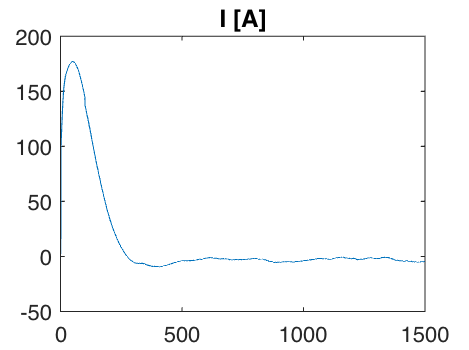

figure;
plot(xCorrStored(2,:));
title("I [A]")

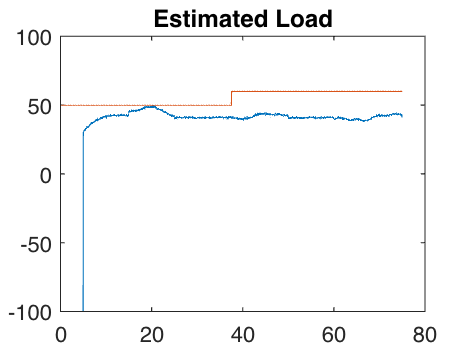

figure;
plot(0:Ts:(N-1)*Ts,estimatedLoad);
title("Estimated Load");
hold on
plot(t,Td);
ylim([-100 100])

## Problem 4:

% Analyze the performance of detection
% Compare IMM to KF using only rotation speed sensor
% Is it possible to jsutify use of current sensor?

## Problem 5:

% Lessons learned

## Additional tools

% Storing figures
if storeFigures
    for i=1:10
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end

## Functions